syms y(t)
eqn = diff(y, 2) == 4*y

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=4\,y\left(t\right)$$

cond = [y(0) == 1, y(1) == 3];
sol = dsolve(eqn, cond)

$$sol = \frac{{\mathrm{e}}^{2\,t}\,\left(3\,{\mathrm{e}}^{2}-1\right)}{{\mathrm{e}}^{4}-1}-\frac{{\mathrm{e}}^{-2\,t}\,\left(3\,{\mathrm{e}}^{2}-{\mathrm{e}}^{4}\right)}{{\mathrm{e}}^{4}-1}$$

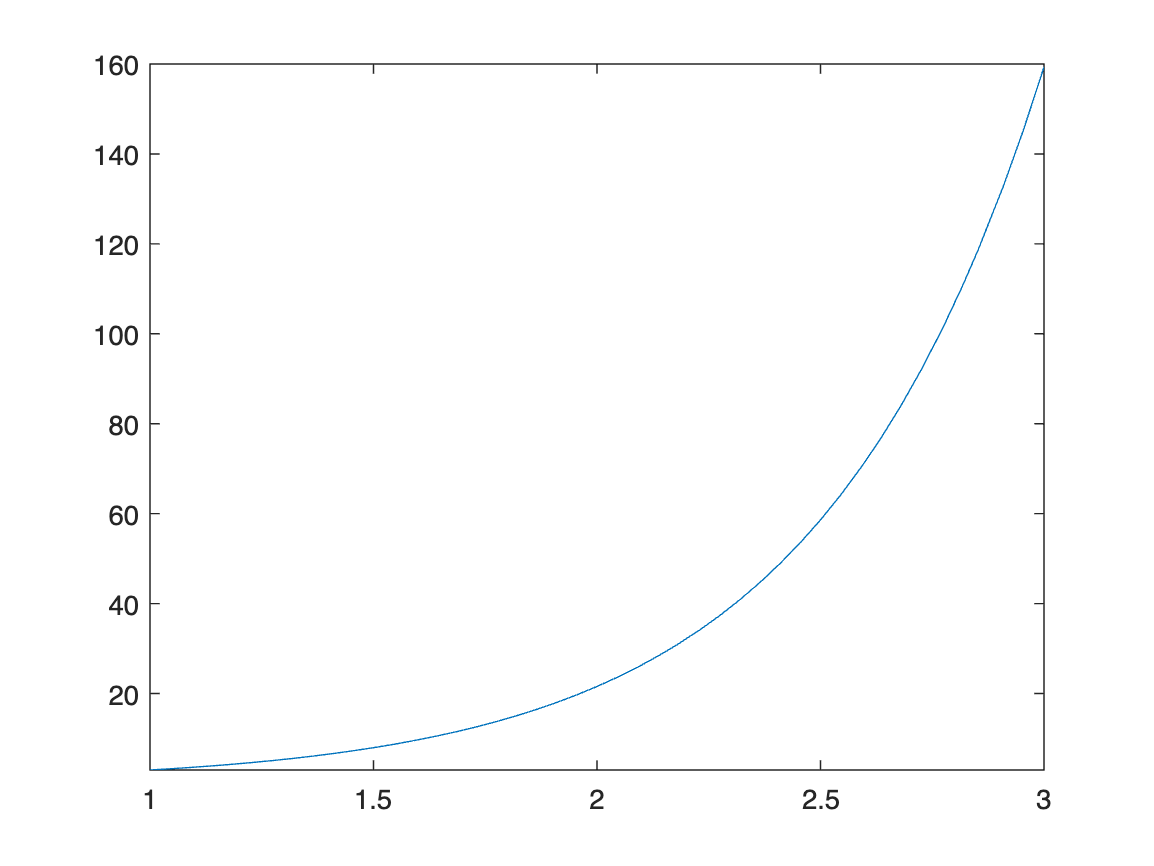

fplot(sol, [1, 3])


a=0;
b=1;
ya=1;
yb=3;
n = 1000;
[t, y] = odeDiffsFinitasTD(a, b, ya, yb, n)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


y =     0.9996
    0.9992
    0.9987
    0.9983
    0.9979
    0.9975
    0.9971
    0.9967
    0.9963
    0.9959


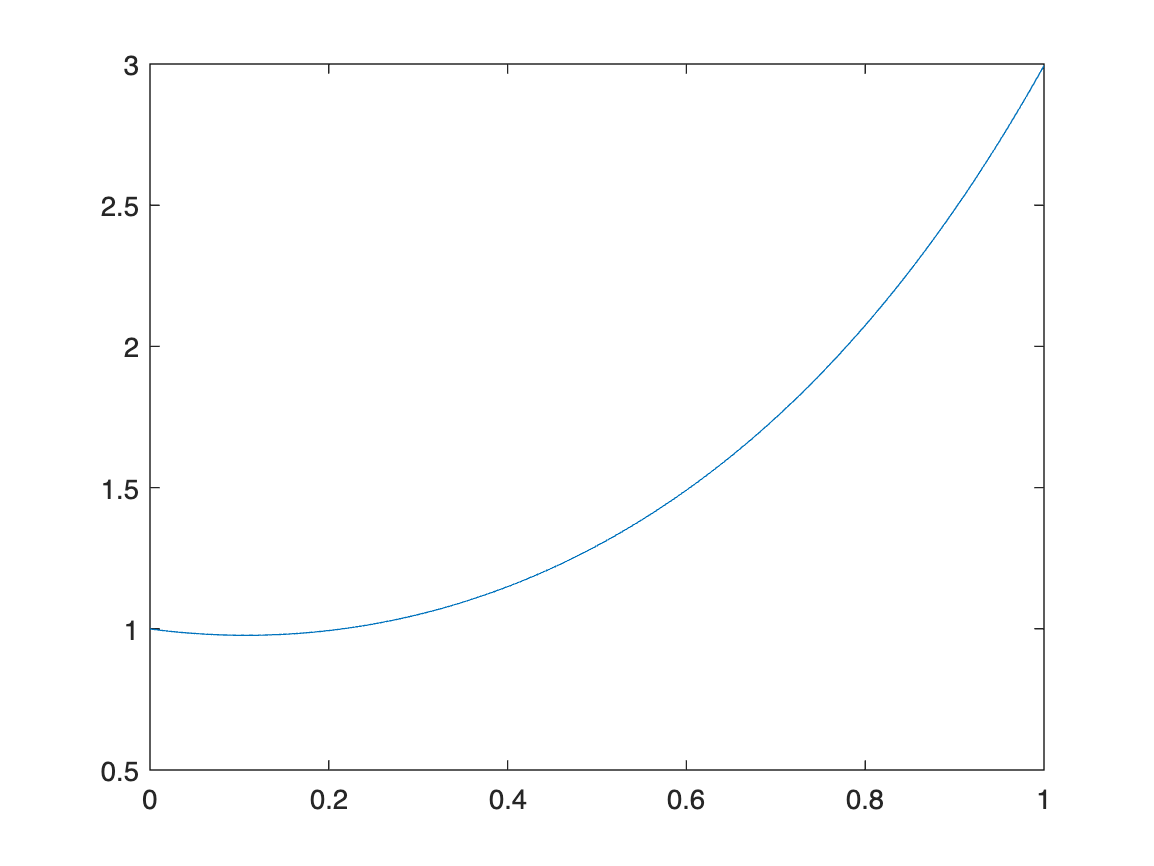

plot(t, y)

%[t,y] = TD(a, b, n)
%plot(t, y)

function [t, y] = odeDiffsFinitasTD(a, b, ya, yb, n)
    h = (b - a)/(n - 1);

    e=-1*ones(1,n);
    f=2*ones(1,n);
    g=-1*ones(1,n);

    c=4*h^2;
    C=c*ones(1,n);
    f=f+C;

    r=zeros(n,1);
    r(1)=ya;
    r(end)=yb;

    t=a:h:b;
    y = Tridiag(e, f, g, r);
end

function [t, y] = TD(a, b, n)
    h = (b - a)/(n - 1);

    f = (-2-4*h^2)*ones(n - 2, 1);
    g = ones((n - 2), 1);
    e = g;
    
    r = zeros;
    r(1) = -1;
    r(n-2) = -3;

    t=a:h:b;
    y = Tridiag(e, f, g, r);
end

function x = Tridiag(e,f,g,r)
    n=length(f);
    for k = 2:n
        factor = e(k)/f(k-1);
        f(k) = f(k) - factor*g(k-1);
        r(k) = r(k) - factor*r(k-1);
    end
    x=zeros(n,1);
    x(n) = r(n)/f(n);
    for k = n-1:-1:1
        x(k) = (r(k)-g(k)*x(k+1))/f(k);
    end
end